clc;
clear;
runtime=80

runtime = 80

for count=1:runtime
Road_length  =100;
car_number   = 80;
acceleration = 2+0.1*count
deceleration =-6.5;
a_d(count)=acceleration/Road_length;
%initial speed
u = 5;
%time limitis
time =1000;
%limit speed
lim = 15;

%repeat loop
for l=1:40
%initial position of car
J = 1:car_number;
A = rand(1,car_number).*Road_length;
x(J,1) =sort(A);
v(J,1)=u;
%minimum distance between cars
x0 = Road_length/car_number;
num = car_number-1;
delT = 0.1;
k = time / delT;
%
average(1) = 0;
t(1) = 0;

for T=2:k
    for J=1:car_number
        if J == car_number
            if J==1
                dis(J,T)= Road_length;
            else
                dis(J,T) = x(1,T-1)-x(J,T-1);
            end
        else
            dis(J,T) = x(J+1,T-1)-x(J,T-1);
        end
        if dis(J,T)<0
            dis(J,T) = Road_length+dis(J,T);
        end
        if dis(J,T) > acceleration * delT
           v(J,T)=v(J,T-1) + acceleration * delT;
        elseif dis(J,T) <= v(J,T-1)
            dis(J,T)=0;
            v(J,T)=0;
        else
           v(J,T)=v(J,T-1)+ deceleration * delT;
        end
        if v(J,T)<0
            v(J,T)=0;
        end
        if v(J,T)>lim
            v(J,T)=lim;
        end
        delta_dis(J,T)=v(J,T)*delT;
        if delta_dis(J,T)>dis(J,T)
            delta_dis(J,T)=dis(J,T);
            v(J,T)=dis(J,T);
        end
        x(J,T)=x(J,T-1)+delta_dis(J,T);
        if x(J,T) > Road_length
           x(J,T)=x(J,T)- Road_length;
        end
    end
      max_speed(T) = max(v(J,T));
      min_speed(T) = min(v(J,T));
      average(T) = sum(v(:,T)) / car_number;
      t(T) = t(T-1) + delT;
end
t(T) = t(T);
x(J,T)=x(J,T);
v(J,T)=v(J,T);
average(T) = average(T);
k_1 = floor(k/2);
d_av = average(1,(k_1):k);
m(l) = mean(d_av);
end
S(count)=std(m);
averagespeed(count) = mean(m);
acc(count)=acceleration;
%percentage
end

acceleration = 2.1000

acceleration = 2.2000

acceleration = 2.3000

acceleration = 2.4000

acceleration = 2.5000

acceleration = 2.6000

acceleration = 2.7000

acceleration = 2.8000

acceleration = 2.9000

acceleration = 3

acceleration = 3.1000

acceleration = 3.2000

acceleration = 3.3000

acceleration = 3.4000

acceleration = 3.5000

acceleration = 3.6000

acceleration = 3.7000

acceleration = 3.8000

acceleration = 3.9000

acceleration = 4

acceleration = 4.1000

acceleration = 4.2000

acceleration = 4.3000

acceleration = 4.4000

acceleration = 4.5000

acceleration = 4.6000

acceleration = 4.7000

acceleration = 4.8000

acceleration = 4.9000

acceleration = 5

acceleration = 5.1000

acceleration = 5.2000

acceleration = 5.3000

acceleration = 5.4000

acceleration = 5.5000

acceleration = 5.6000

acceleration = 5.7000

acceleration = 5.8000

acceleration = 5.9000

acceleration = 6

acceleration = 6.1000

acceleration = 6.2000

acceleration = 6.3000

acceleration = 6.4000

acceleration = 6.5000

acceleration = 6.6000

acceleration = 6.7000

acceleration = 6.8000

acceleration = 6.9000

acceleration = 7

acceleration = 7.1000

acceleration = 7.2000

acceleration = 7.3000

acceleration = 7.4000

acceleration = 7.5000

acceleration = 7.6000

acceleration = 7.7000

acceleration = 7.8000

acceleration = 7.9000

acceleration = 8

acceleration = 8.1000

acceleration = 8.2000

acceleration = 8.3000

acceleration = 8.4000

acceleration = 8.5000

acceleration = 8.6000

acceleration = 8.7000

acceleration = 8.8000

acceleration = 8.9000

acceleration = 9

acceleration = 9.1000

acceleration = 9.2000

acceleration = 9.3000

acceleration = 9.4000

acceleration = 9.5000

acceleration = 9.6000

acceleration = 9.7000

acceleration = 9.8000

acceleration = 9.9000

acceleration = 10

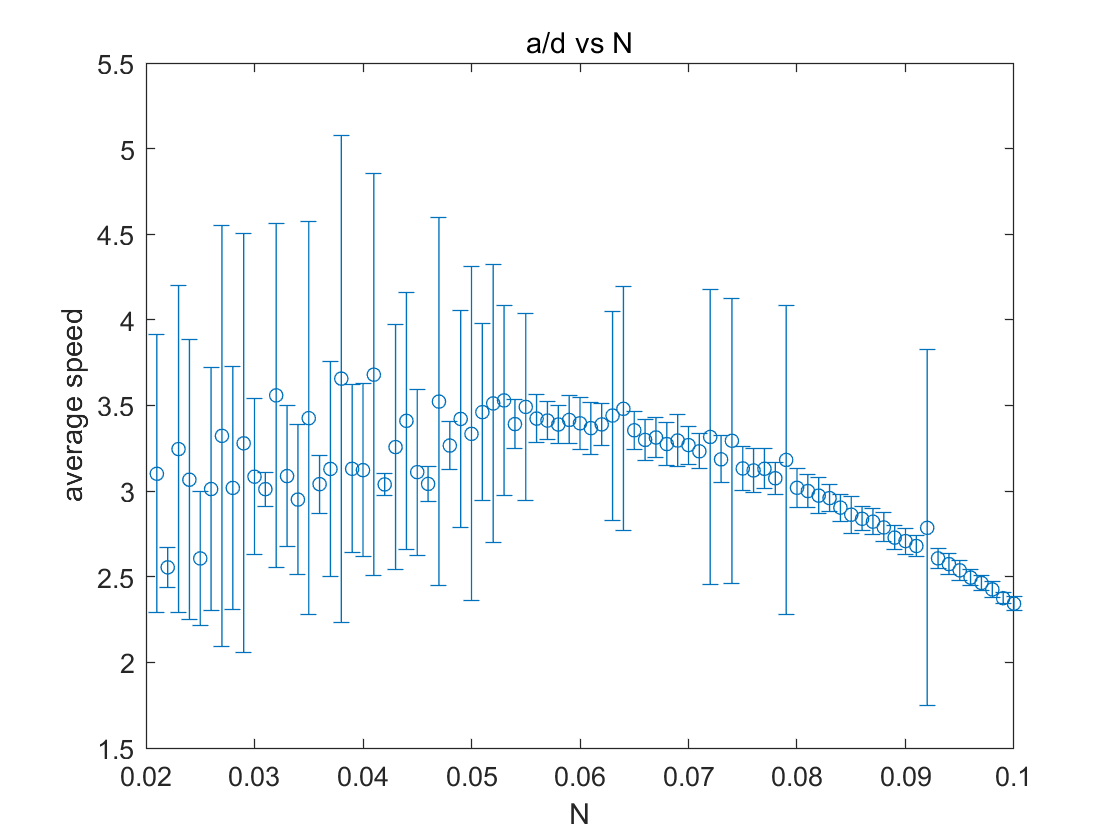

errorbar(a_d,averagespeed,S,"o","MarkerSize",5)
title("a/d vs N") 
xlabel('N')
ylabel('average speed')